# Multiband FIR Filter

Design a 46th-order FIR filter that attenuates normalized frequencies below $0.4\pi$ rad/sample and between $0.6\pi$ and $0.9\pi$ rad/sample. Call it `bM`.

ord = 46;

low = 0.4;
bnd = [0.6 0.9];

apple = [1 6]

apple =      1     6



bM = fir1(ord,[low bnd]);

Redesign `bM` so that it passes the bands it was attenuating and stops the other frequencies. Call the new filter `bW`. Use `fvtool` to display the frequency responses of the filters.

bW = fir1(ord,[low bnd],'DC-1');


hfvt = fvtool(bM,1,bW,1)

hfvt =   Figure (filtervisualizationtool) with properties:

      Number: 2
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 1080 533]
       Units: 'pixels'

  Use get to show all properties


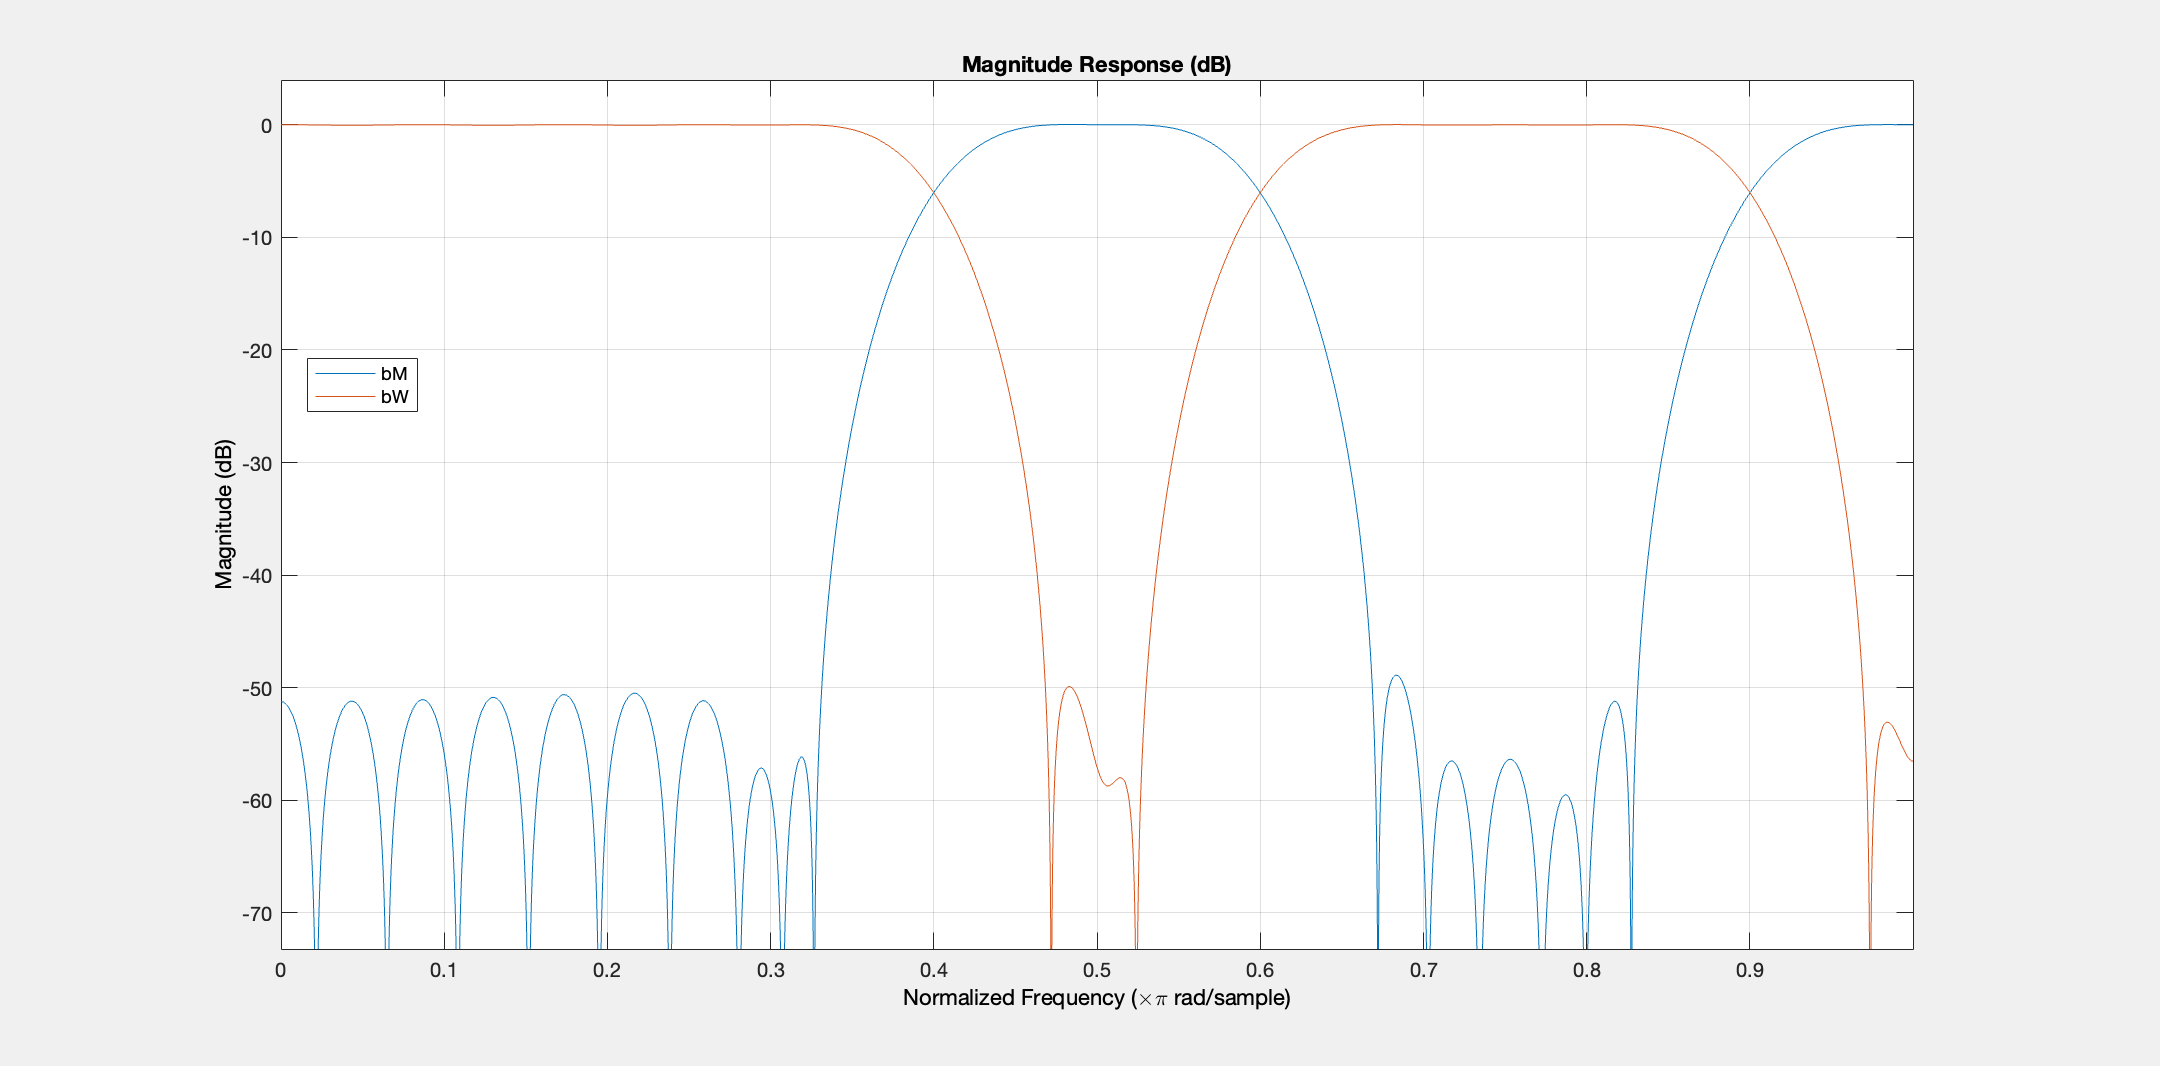

legend(hfvt,'bM','bW')

Redesign `bM` using a Hann window. (The `'DC-0'` is optional.) Compare the magnitude responses of the Hamming and Hann designs.

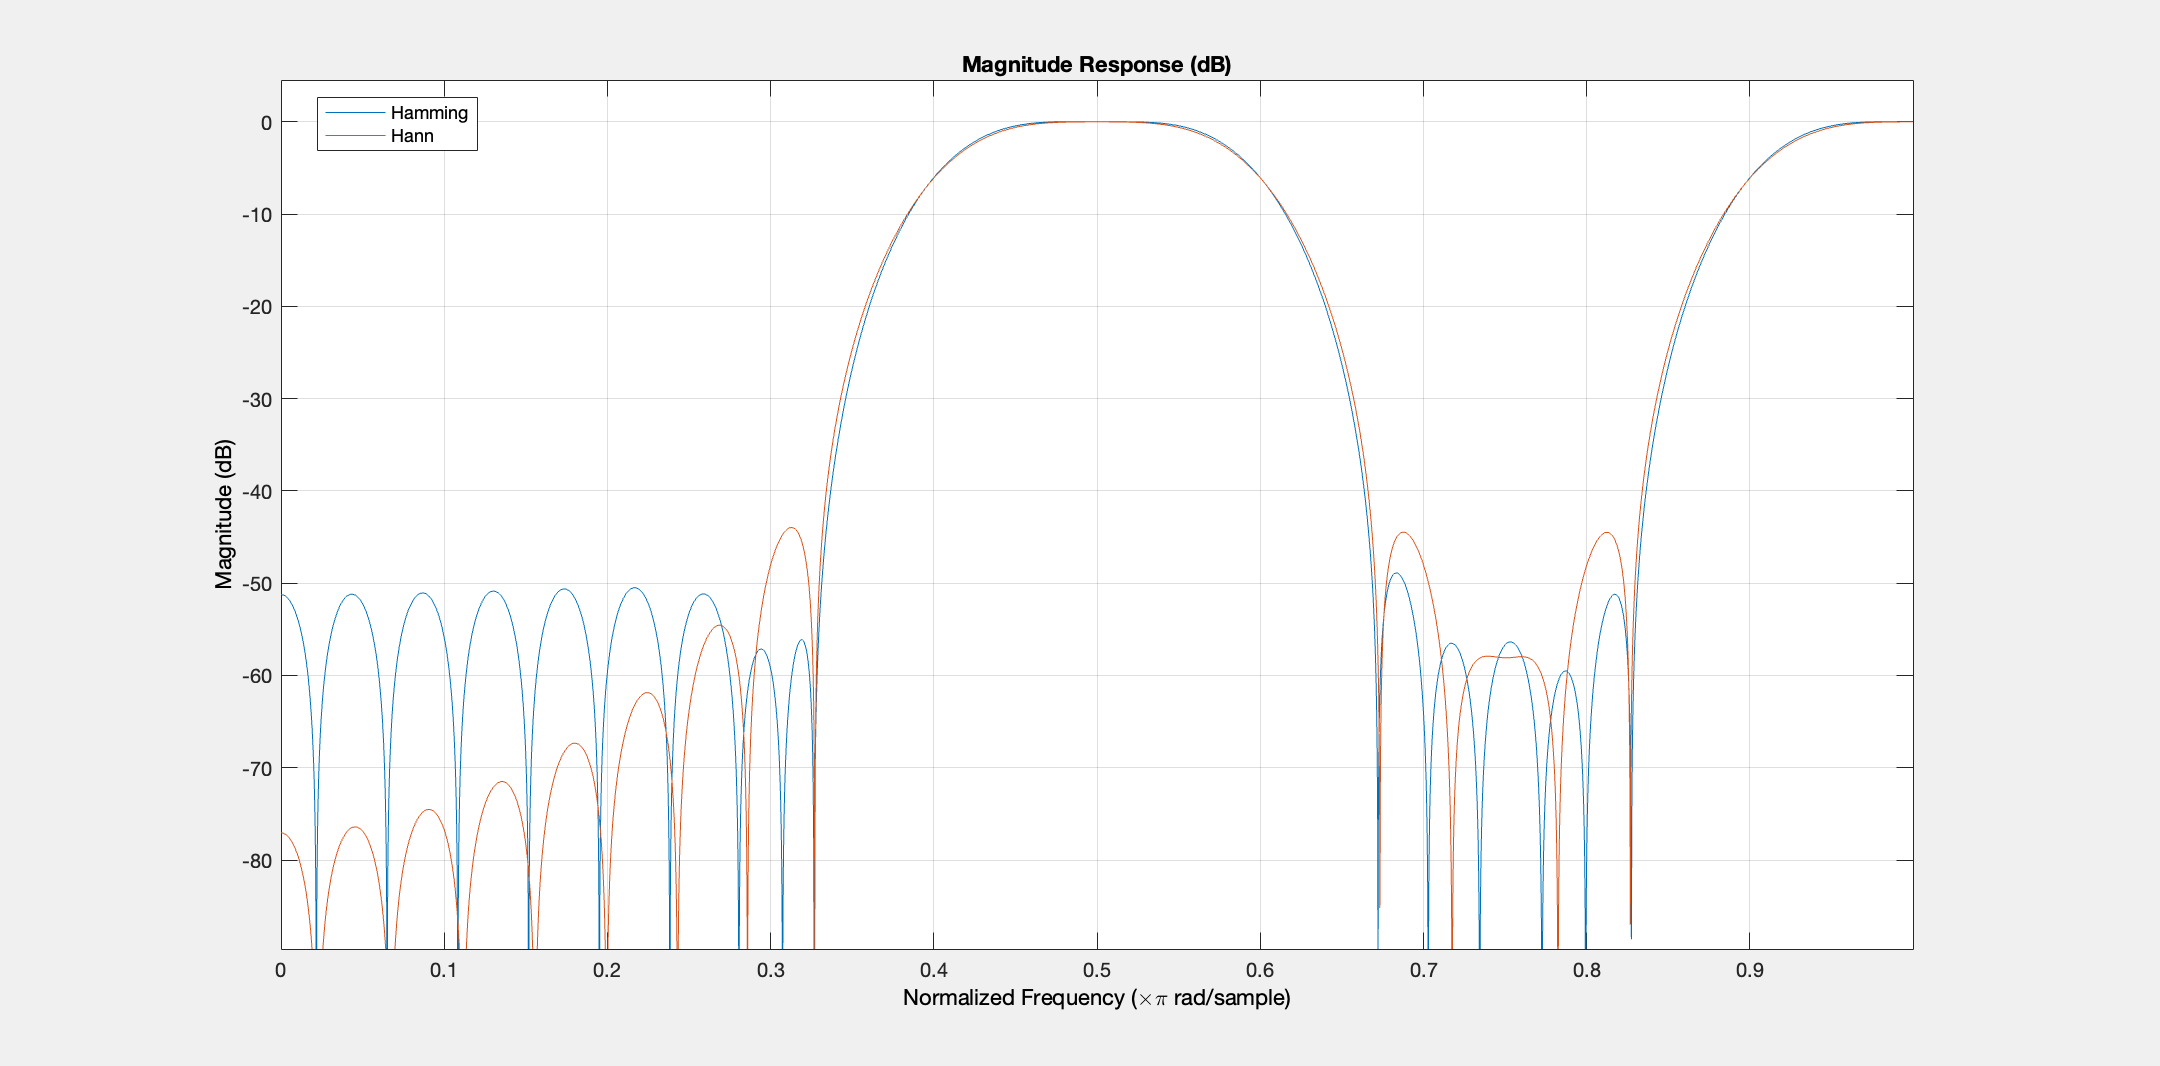

hM = fir1(ord,[low bnd],'DC-0',hann(ord+1));

hfvt = fvtool(bM,1,hM,1);
legend(hfvt,'Hamming','Hann')

Redesign `bW` using a Tukey window. Compare the magnitude responses of the Hamming and Tukey designs.

tW = fir1(ord,[low bnd],'DC-1',tukeywin(ord+1));

hfvt = fvtool(bW,1,tW,1);

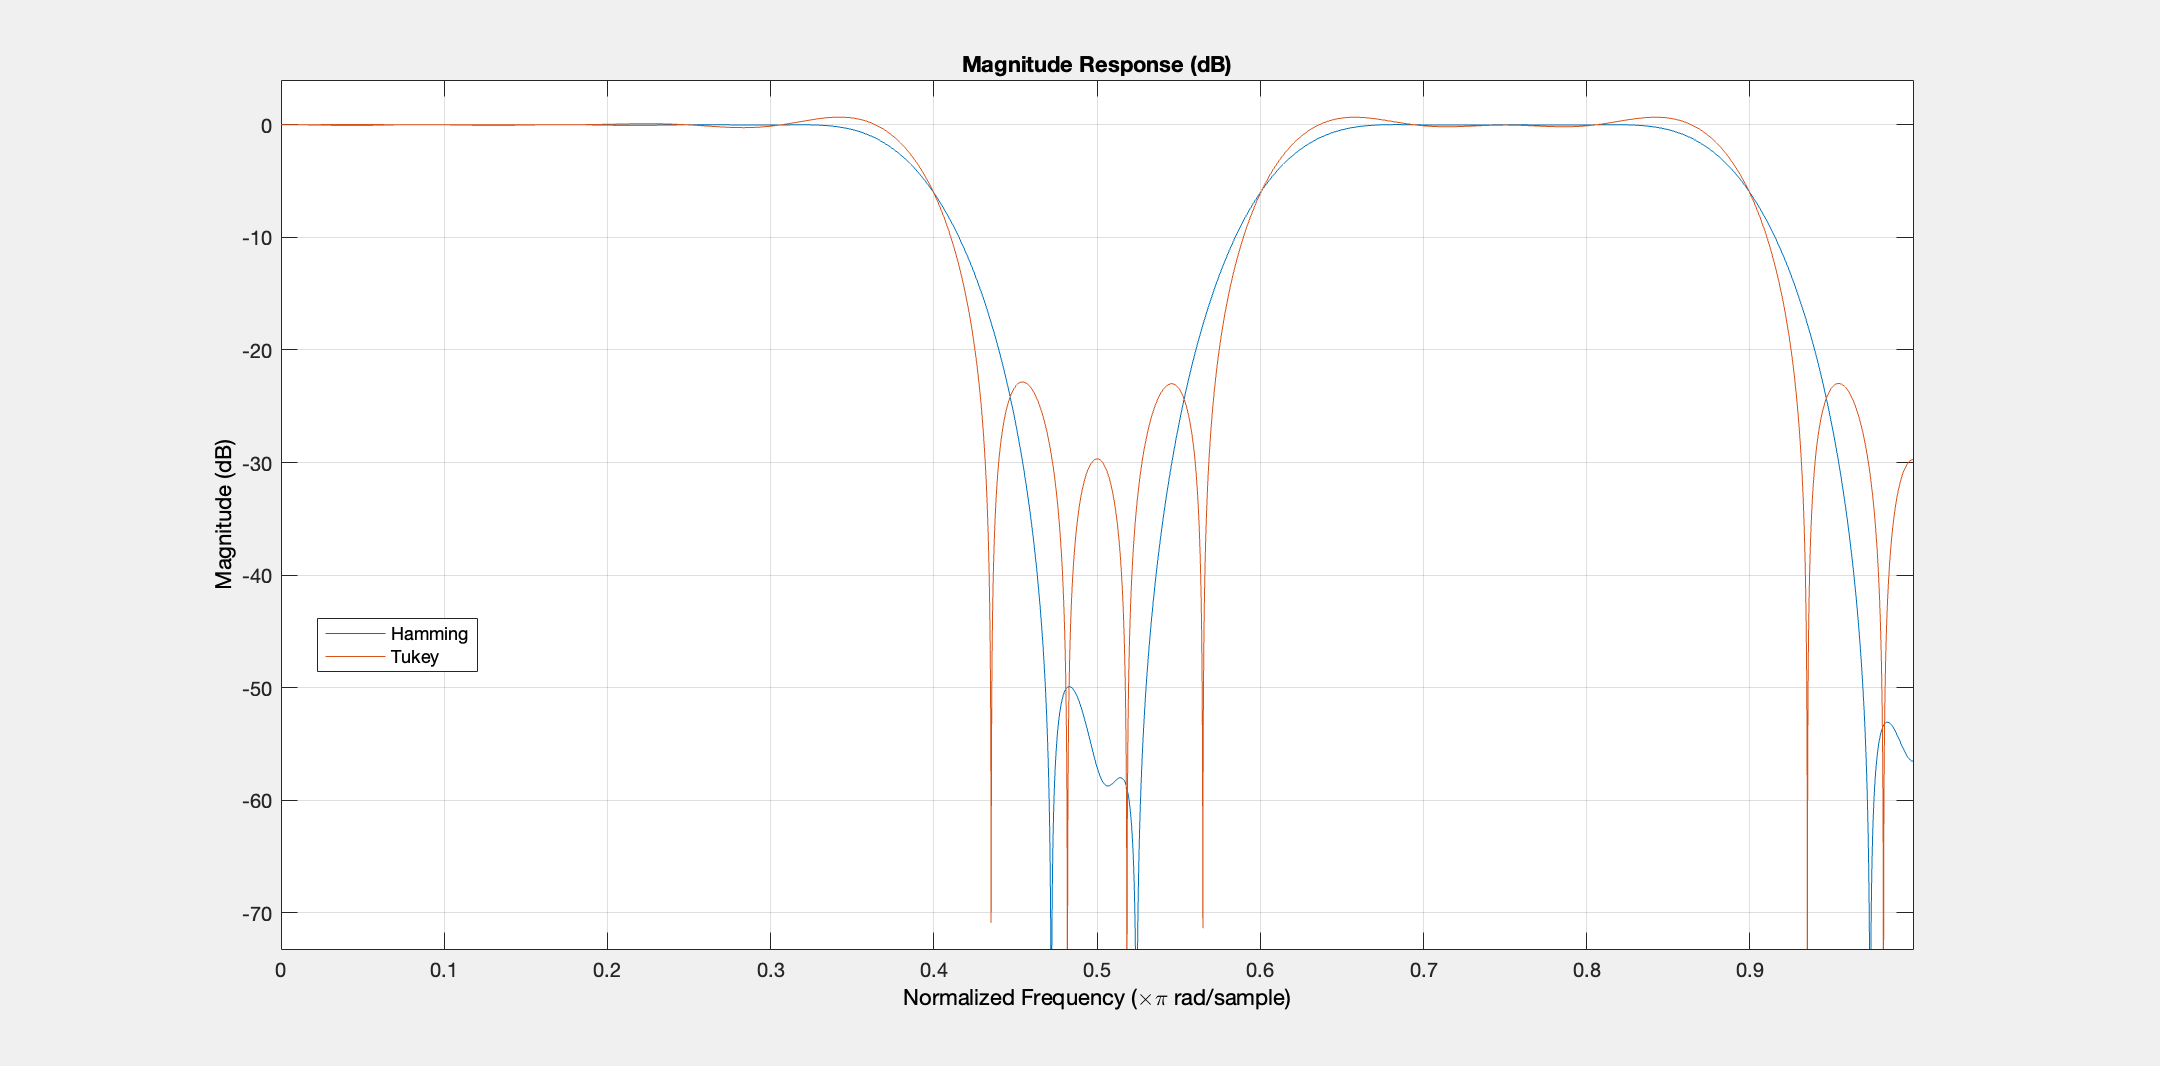

legend(hfvt,'Hamming','Tukey')

*Copyright 2012 The MathWorks, Inc.*